# Modelling coupled miscible fluid flow and transport processes 

Fluid flow in subsurface aquifers and reservoirs may be undertaken under variable fluid properties. For instance, fluid viscosity changes dynamically as a function of local fluid concentration, temperature, or pressure conditions. These changes induce a tight dependence between the flow and solute/heat transport processes. Many applications belong to these category:

- In the context of miscible Enhanced Oil Recovery a less viscous fluid (i;e. cold water, hot water, carbon dioxide, surfactants, etc) is often injected into the host formation to assist in the oil recovery process which involves a number of injection and production wells geographically placed following a given pattern. The oil volume in less permeable regions in the reservoir is best recovered when the injected fluid has lower viscosity leading to early breakthrough and higher recovery in production wells. 

- Aquifer remediation technologies require optimal placement of a number of active and passive wells to decontaminate an initially polluted site by driving the concentration distribution below a national (or international) target regulation threshold. Characterization of the chemical composition and viscosity of injected aqueous solution plays an important role in this design. 

- Pressure control in a deep geothermal reservoir requires very often the design of injection and production doublet wells. Extracted hot fluid is cooled in an external facility to produce heat or energy and reinjected back into the host formation at a significantly lower temperature. Since the water (oe brine) viscosity is a strong function of temperature the injected fluid has significant higher viscosity and therefore lower mobility thus retarding the heat front dissipation and enhancing the half-life of the doublet. 

The goal of this tutorial is to learn how to model these processes. We will consider a simple two-dimensional example with a highly heterogeneous distribution of the permeability and porosity fields. These fields are extracted from the first layer of the SPE10 comparative solution project realization. 

An injection and production wells are placed at the lower left and upper right corners of the computational domain. Next, three simulations will be performed: (i) a reference simulation with an equal viscosity ratio (ratio of injected fluid viscosity to that of the resident fluid), (ii) a second simulation with a gradually increasing viscosity ratio, and (iii)  a third simulation with a gradually decreasing viscosity ratio.  

## Data preparation and simulations setup 

Lest's start by constructing the computational domain:

% Domain size along X, Y & Z directions
dom = RecDomain([365.76,670.56,0.6096]);
Dx = dom.Lx; Dy = dom.Ly; Dz = dom.Lz;

Set the number of cells along X, Y, and Z directions: 

Grid.Nx = 60;   Grid.Ny = 220;   Grid.Nz = 1; 
Nx = Grid.Nx;   Ny = Grid.Ny;    Nz = Grid.Nz; 

Calculate grid sizes along each space direction:

Grid.hx = (Dx/Nx);
Grid.hy = (Dy/Ny);
Grid.hz = (Dz/Nz);

Set total number of gridblocks:

Grid.N = Grid.Nx*Grid.Ny*Grid.Nz;
N = Grid.N;

Set Grid data: 

Grid.V = (Dx/Nx)*(Dy/Ny)*(Dz/Nz);                        % Cell volumes
Grid.K = 1.4e-11.*ones(3,Nx,Ny,Nz);                      % Unit-Darcy permeability
Grid.compr = 4.4e-10.*ones(Grid.Nx,Grid.Ny,Grid.Nz);     % compressibility

Load porosity data from a saved mat file:

load '..\data\spe_layer1_phi.mat' phi_layer;
phi = phi_layer; clear phi_layer;
phi = max (phi(:), 1e-3); % to avoid zero porosity cells
Grid.por = reshape(phi',Nx,Ny,Nz); 

Load permeability data from a saved mat file: 

load '..\data\spe_layer1_perm.mat' perm_layer;
Grid.K = perm_layer*9.869232667160130e-13;
Grid.K = reshape(Grid.K',3,Nx,Ny,Nz); 

Draw porosity and log10-permeability maps: 

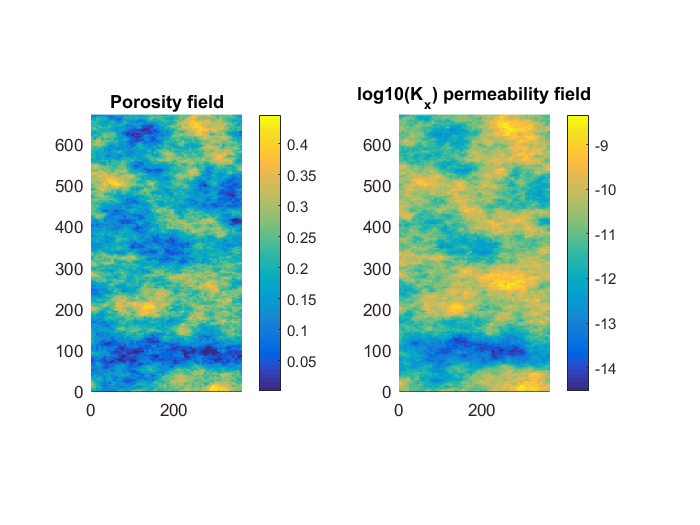

G = cartGrid(0:Dx/Nx:Dx, 0:Dy/Ny:Dy);

figure;

subplot(1,2,1);
PlotCellData(G, phi, 'EdgeColor','none');
%colormap(jet(16));
axis tight equal; colorbar, title('Porosity field');

subplot(1,2,2);
PlotCellData(G, reshape(log10(Grid.K(1,:,:,:)),N,1), 'EdgeColor','none');
axis tight equal; colorbar, title('log10(K_x) permeability field');

clear phi;

Next, add injection / production wells and their respective flow rates:

% Cell-centered injection/production flow rates
flow_rate  = 100/3600;
Qw         = zeros(N,1);
Qw([1 N])  = [+flow_rate -flow_rate];

Initialize the only fluid used in this model:

% fluid properties units: density (Kg/m^3), initial viscosity (Pa.s)
water = Fluid('water',[1000, 1e-3]);

Initialize fluid pressure in the computational domain to 100 bars:

P = 100e5.*ones(Nx,Ny,Nz);

Define time stepping parameters including total simulation time, T, the number of time steps, nt, and the constant time step, dt in seconds

day = 3600*24;                     % seconds/day
T   = 5*day;                       % 5 days
nt  = 30;                          % number of time steps
dt  = T/nt;                        % time step

Setup options for the Newton-Raphson solver:

opt.tol     = 1e-9;
opt.maxiter = 50;

We wil now solve a solute transport problem. A unit concentration is carried from the injection well at the lower left corner:

D = 1e-9.*ones(3,Nx,Ny,Nz); % uniform diffusion coefficient through the domain 
C1 = zeros(N,1); C1(1) = 1; % unit input concentration at the injector & zero otherwise
Grid.sat = ones(Nx,Ny,Nz);  % unit saturation everywhere 

Go through the main diffusive-convective solute transport time loop. Advection and diffusion processes are simulated by splitting the advection and diffusive parts symmetrically as suggested by Strang to increase the concentration accuray by minimizing the time-splitting error:

tic;                        % start timing the time marching loop
    
% call TPFA flow solver for single-phase flow (we assume steady state flow here)
[~,V] = Pressure(Grid,water,Qw);   

for t=1:nt
    
    fprintf('\nSolving solute transport problem. Time = %f days\n', t*dt/day);
   
    % call the fully implicit first-order upwind convective transport for a half time step
    C_bar = ImplicitConcentration(Grid,C1,V,Qw,dt/2,opt); 
      
    % solve implicitly the diffusion problem for this time step
    [C_bar,~] = Diffusion(Grid,D,C_bar,dt);
   
    % do advection step for the remaining half time step
    C1 = ImplicitConcentration(Grid,C_bar,V,Qw,dt/2,opt); 

    % note: C_bar is the intermediate concentration after the first advection step 
    %             and the diffusive step
end


Solving solute transport problem. Time = 0.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 0.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 0.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 0.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 0.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 1.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 2.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 3.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 4.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Solving solute transport problem. Time = 5.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps


toc;

Elapsed time is 8.663168 seconds.


For this problem the numerical solution is obtained quickly after only few seconds. Letes examone the shape of the solute plume after 5 days of continuous injection. 

Plot the final concentration plume with 11 filled contour lines corresponding to iso-concentrations from 0 to 1 with a 0.1 spacing:

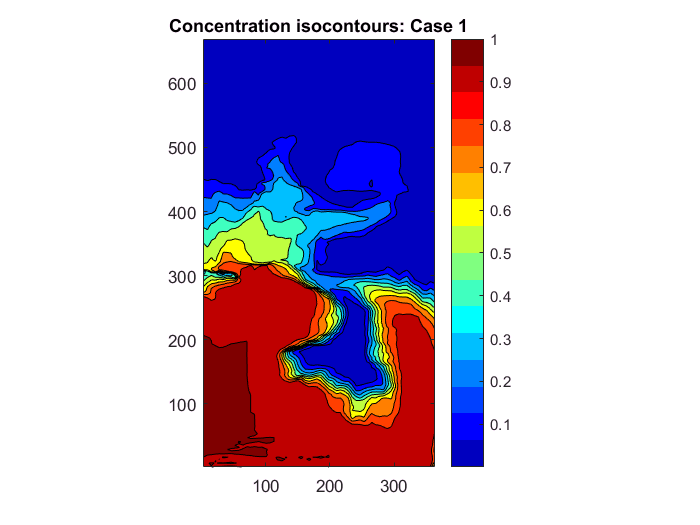

figure; 

% plot solute concentration for this first simulation
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(C1,Nx,Ny)','LevelList',0:0.1:1);
colormap(jet(16));
axis tight equal; colorbar, title('Concentration isocontours: Case 1');

## Case 2: miscible flow and transport - increasing viscosity ratio

Now, we will repeat the last simultion but the flow and solute transport equations are coupled by a favorable viscosity ratio which is assumed to dependent linearly on the solute concentration following the Doles-Jones correlation:


$$\mu(C) = \mu(C_0)(1+\lambda C)$$


where:

$\lambda > 0$ is a correction term which depends on the nature of the solute being injected.

$\mu(C_0)$ is the viscosity at the reference concentration $C_0$.

We define this viscosity dependence on the concentration with the help of an anonymous function. In the MATLAB scripting language an anonymous function is expressed as an analytic function handle (the @) followed by declaration of the dependent variables (herein c vector) and then the analytic function expression. In this simulation we set $\lambda$ to +10 such that the viscosity magnitude will increase at a maximum by one order of magnitude (i.e. at c=1). 

visc = @(c) 1e-3*(1+10.*c);

Now, let's do a coupled miscible flow and transport simulation time stepping loop. The key difference with the previous simulation is that the flow solver is repeatedly called at the beginning of each time step with updated cell-centered viscosities in each grid cell. This task is simply performed by calling our previously defined anonymous viscosity function and setting this new array to target fluid property. Next, the solute transport algorithm is identical to that discussed in the previous case.

Concentrations for this second case will be stored in C2 array to enable comparaison with results of first simulation stored in C1 array.

C2 = zeros(N,1); C2(1) = 1;

tic;              % start timing the time marching loop
for t=1:nt
    
    fprintf('\nUpdating the flow.\n');
    
    % viscosity recalculation 
    water.viscosity = visc(C2); 
   
    % call TPFA flow solver for single-phase flow 
    [P,V] = Pressure(Grid,water,Qw);   
    
    fprintf('\nSolving solute transport problem. Time = %f days\n', t*dt/day);
   
    % call the fully implicit first-order upwind convective transport for a half time step
    C_bar = ImplicitConcentration(Grid,C2,V,Qw,dt/2,opt); 
   
    % solve implicitly the diffusion problem for this time step
    [C_bar,~] = Diffusion(Grid,D,C_bar,dt);
   
    % do advection step for the remaining half time step
    C2 = ImplicitConcentration(Grid,C_bar,V,Qw,dt/2,opt);

end


Updating the flow.



Solving solute transport problem. Time = 0.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 5.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps


toc;

Elapsed time is 8.691799 seconds.


Let's plot the new results:

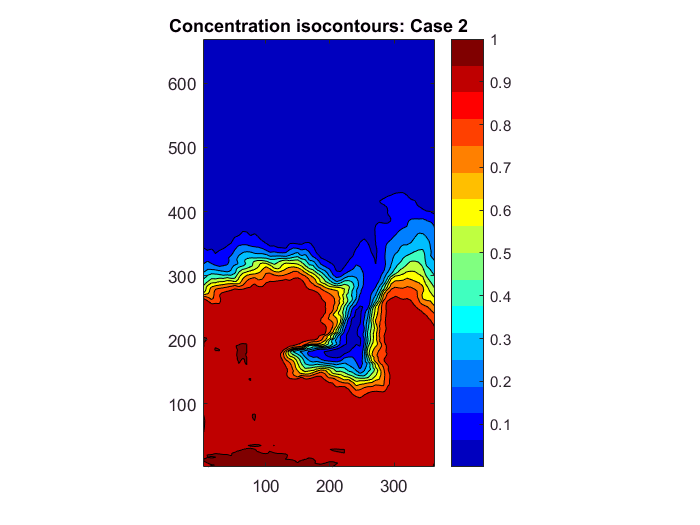

figure; 

% plot solute concentration 
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(C2,Nx,Ny)','LevelList',0:0.1:1);
colormap(jet(16));
axis tight equal; colorbar, title('Concentration isocontours: Case 2');

When injecting a more viscous fluid the solute plume advancement is less restricted so as shown in the last figure the concentration fronts are more compressed and a higher concentration gradient is observed at the advancing front unlike in the first case where it is more diffusive in high permeability regions. However, since the fluid is less mobile solute diffusion is more pronounced in less permeable zones than in the first case where the fluid residence time is shorter. Thus there is less fluid mixing between waters in more and less permeable zones in the first case than in the second one. 

## Case 3: miscible flow and transport - decreasing viscosity ratio

Now we will consider a similar problem except that the injected fluid is less viscous. By setting $\lambda$ to -10  viscosity is variable over one order in magnitude in the opposite direction when considering the second case. 

Concentrations for this third simulation are stored in C3 array.

visc = @(c) 1e-3*(1-10.*c);
C3 = zeros(N,1); C3(1) = 1;

tic;              % start timing the time marching loop
for t=1:nt
    
    fprintf('\nUpdating the flow.\n');
    
    % viscosity recalculation 
    water.viscosity = visc(C3); 
   
    % call TPFA flow solver for single-phase flow 
    [P,V] = Pressure(Grid,water,Qw);   
    
    fprintf('\nSolving solute transport problem. Time = %f days\n', t*dt/day);
   
    % call the fully implicit first-order upwind convective transport for a half time step
    C_bar = ImplicitConcentration(Grid,C3,V,Qw,dt/2,opt); 
   
    % solve implicitly the diffusion problem for this time step
    [C_bar,~] = Diffusion(Grid,D,C_bar,dt);
   
    % do advection step for the remaining half time step
    C3 = ImplicitConcentration(Grid,C_bar,V,Qw,dt/2,opt);

end


Updating the flow.



Solving solute transport problem. Time = 0.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 0.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 1.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 2.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 3.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.166667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.333333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.500000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.666667 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 4.833333 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps



Updating the flow.



Solving solute transport problem. Time = 5.000000 days


Newton-Raphson iteration converged in 1 steps
Newton-Raphson iteration converged in 1 steps


toc;

Elapsed time is 10.769796 seconds.


Let's plot the new results:

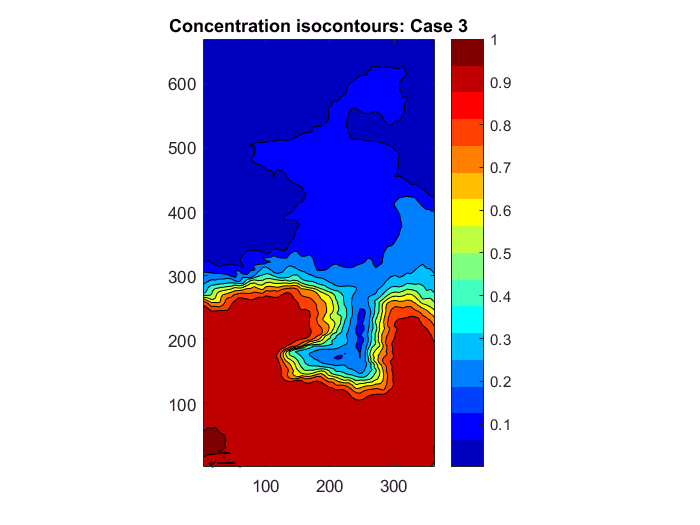

figure; 

% plot solute concentration 
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(C3,Nx,Ny)','LevelList',0:0.1:1);
colormap(jet(16));
axis tight equal; colorbar, title('Concentration isocontours: Case 3');

The most important outcome of this third simulation is that the first concentration fronts of the solute plume when injecting a less viscous fluid are spreading much rapidly. As such, solute breakthrough in the production well is expected to occur much earlier than in the previous cases. 